# DFS Algorithm Build-Test Documentation

This document is created at the same time of building the main DFS algorithm. It includes the design thoughts and test cases, and is a good starting place for beginners to have an overall understanding of this repo.

## DFS Concept

The DFS search algorithm starts with a very simple heuristic: search the latest found path first. A more comprehensive illustration is given in Figure 1 below, which we will walk you through shortly.

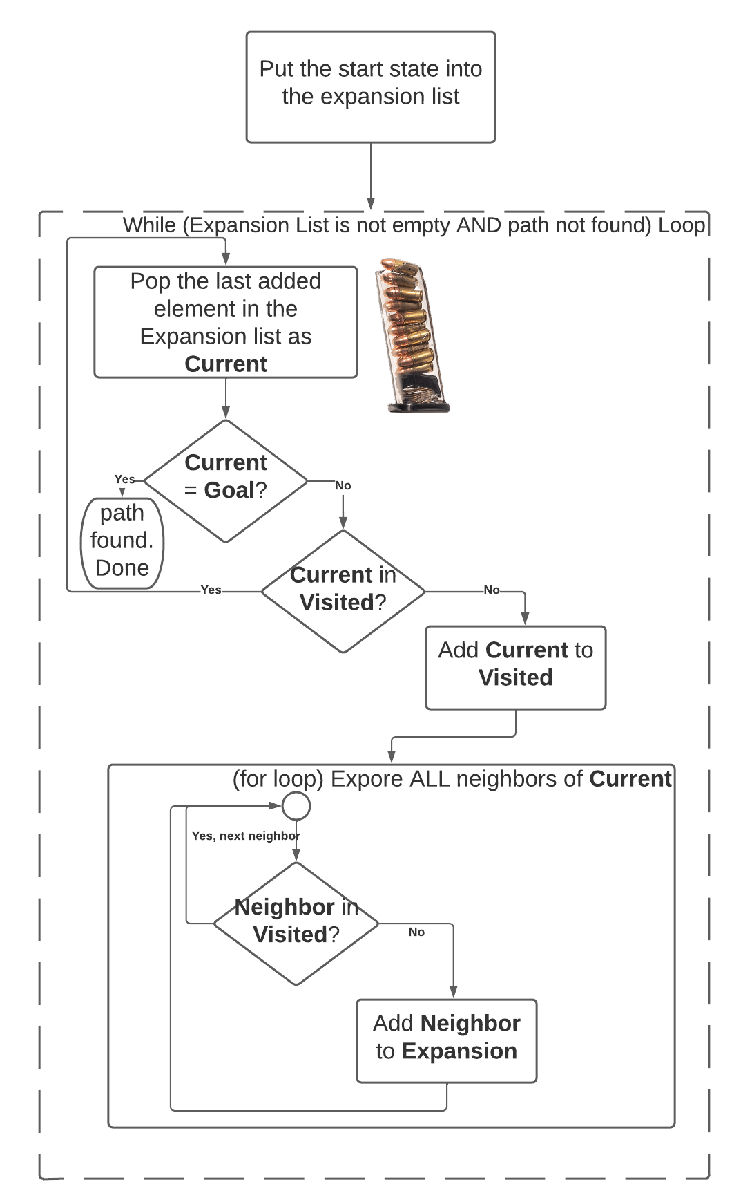

Figure 1. Illustration of the DFS search algorithm

The space we are searching is first of all discretized, and each possible point in the space is called a state. There will always be a starting point $P_0$ and usually at least one end point $P_{\textrm{end}}$. The goal is to find a valid path from $P_0$ to $P_{\textrm{end}}$. The DFS keeps two lists: expansion list $E$ and visited list $V$. At the very beginning, we put the starting point $P_0$ and the action to get there (which is [ ] or empty) into the expansion list $E=\left\lbrace \left(P_0 ,\textrm{empty}\right)\right\rbrace$. Then a random or preferred action in a finite m-actions set $a_1 \in A=\left\lbrace a_i \left|i=1,\cdots ,m\right.\right\rbrace$ is taken, and if the new resulting state $P_1$ is not in the visited list $V$, then we add it to the expansion list: $E=\left\lbrace \left(P_0 ,\textrm{empty}\right)\;,\left(P_1 ,a_1 \right)\right\rbrace$, and move on to the next possible action $a_2$ and evaluate again if the resulting state is visited. We basically try all the possible actions in $A$ and see if the resulting states are visited, and throw those not visited into the expansion list $E$. After all possible actions are exhausted, we go back and look at our expansion list $E$, and pick the latest added state-actions pair as the current state, and perform the sweep of all possible actions starting from this current state again. We do not stop until either the end point $P_{\textrm{end}}$ is reached, or the expansion list is empty, or some imposed maximum iteration is reached.

## DFS Peudo Code

The peudo code of the DFS algorithm is the following:

% % Inputs: grid, start, end
% % Output: final_path
%
% V = {};
% E = {};
% E.append(start,[]);
% final_path = [];
%
% while (length(E)>0 && final_path == [])
%   current = E.pop();
%   [cur_state, cur_path] = unpack(current);
%   if cur_state == end
%       final_path = cur_path
%   elseif ~ismember(cur_state,V)
%       visited.append(cur_state);
%       for a in A
%           next = transition(grid,cur_state,a);
%           if ~ismember(next,V)
%               next_path = cur_path;
%               next_path.append(a);
%               E.append(next,next_path);
% return final_path

The `grid` variable is an occupancy matrix or occupancy map that dictates whether a certain state in the grid is valid or not. The `transition`() function relies on the grid, current state and an action to evaluate the next state after applying the action. If the next state is invalid (occupied in the grid), then the next state will remain the same as before.

## Code Implementation

### The transition function

The transition function is problem specific, in this repo, we first provide a transition function example of a simple 4-direction grid-world maze, then we provide a more interesting example of clothoid-based path-planning state transition.

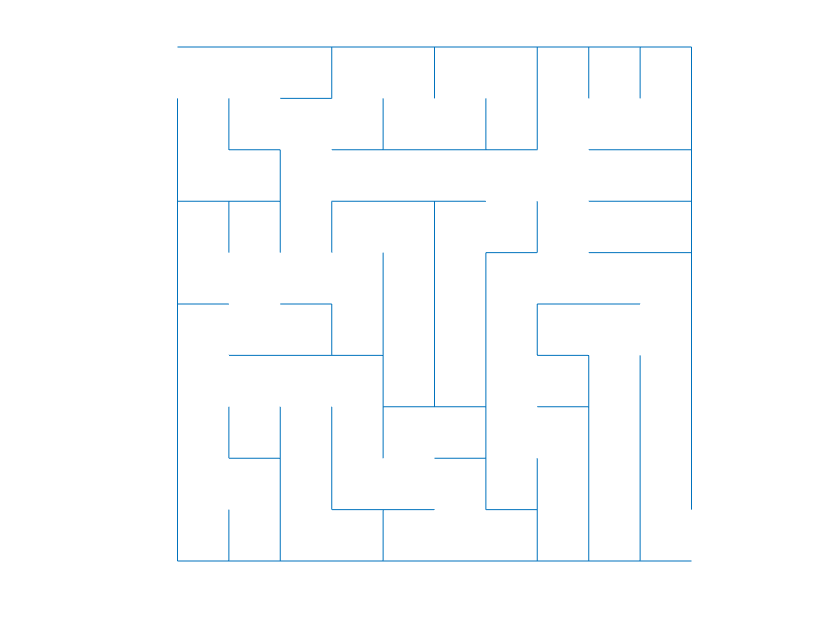

% testing the grid-world maze transition function
addpath('maze'); % add the maze package to search path
% generate a random 10x10 maze
mz = mazeCls(10,10,'c');
h=figure();
mz.show_maze(h)

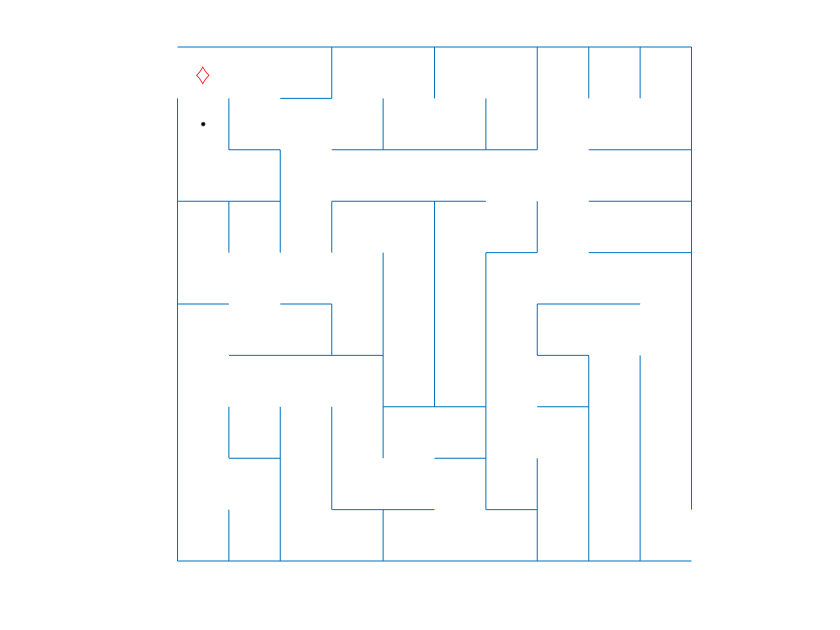

% we visualize and test the maze transition function
cur_state = [1,1]; % start point
action = 3; % up 1, right 2, down 3, left 4
next_state = mz.transition(cur_state,action);
mz.show_transition(cur_state,action);

The maze transition function passes the test.

### The DFS function

The DFS function is implemented using a class-based definition `dfsCls`. The class object stores the exploration list `e_list` and the visited list `v_list` as cell arrays.

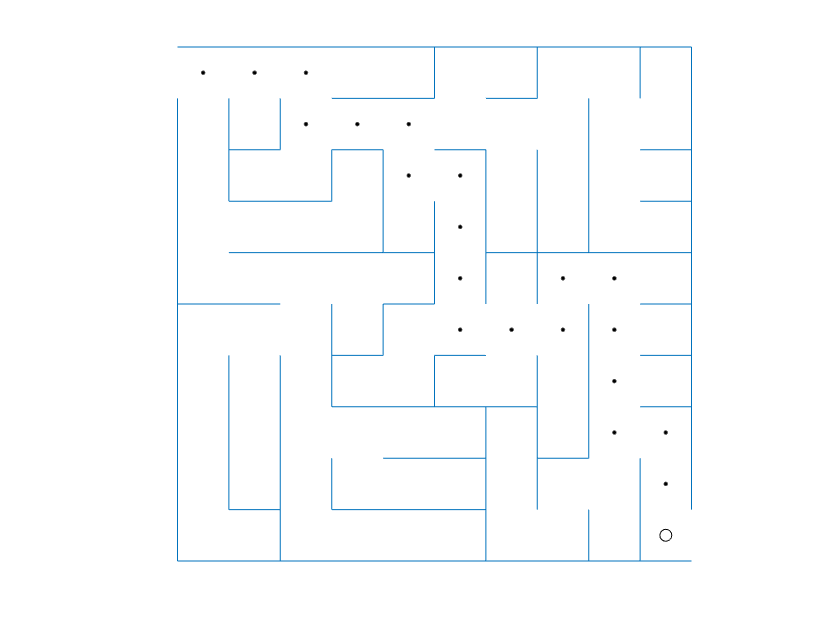

% testing the dfs function
mz = mazeCls(10,10,'c');
dfsObj = dfsCls(mz);
start = [1,1];
goal = [10,10];
final_path = dfsObj.dfs(start,goal);
% visualize the path
h=figure();
dfsObj.problem.show_maze(h);
dfsObj.problem.show_path(final_path,h);

The dfs function passes the test.